warning('off')

toy_samples = 50;
nb_inputs = 2;
nb_outputs = 2;

bf = {@theta1, @theta2, @theta3, @theta4, @theta5, @theta6, @theta7, @theta8, @theta9, @theta10};
r = 3;
sampling_points = randn(nb_inputs, toy_samples);

Jac = zeros(nb_outputs, nb_inputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');
    [~, Jac(1,:,i)] = dlfeval(@f1, point);
    [~, Jac(2,:,i)] = dlfeval(@f2, point);
end

[W_toy, V_toy, H_toy, c_toy] = CTD(Jac, bf, r, sampling_points);
U = {W_toy, V_toy, H_toy};
frob(cpdres(Jac, U)) / frob(Jac)

ans = 0.0160

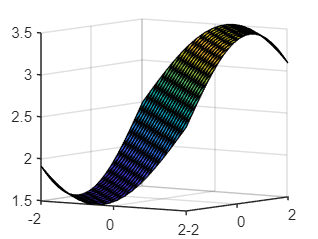


x = linspace(-2,2,20);
y = x';
z = zeros(20);
zb = zeros(20,20,2);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f1, point);
        zb(i,j,:) = fbar([x(i); y(j)], W_toy, V_toy, c_toy);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

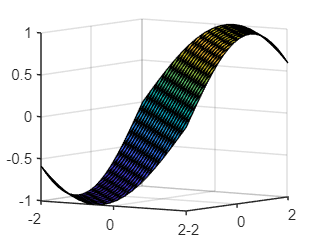

% Benadering
surf(x,y,zb(:,:,1))
view([35.05 6.20])

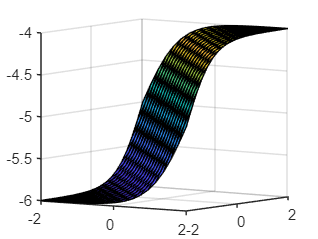



z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f2, point);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

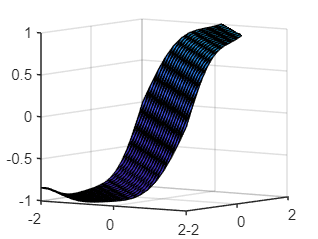

% Benadering
surf(x,y,zb(:,:,2))
view([35.05 6.20])
zlim([-1 1])

function [f,grad] = f1(x)
    f = 2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f] = fbar(u, W, V, c_toy)
    P = zeros(3,1);
    x = V' * u;
    for i=1:3
        P(i,1) = c_toy((10* (i - 1)) + 1) * x(i) + ...
                 c_toy((10* (i - 1)) + 2) * x(i)^2 + ...
                 c_toy((10* (i - 1)) + 3) * x(i)^3 + ...
                 c_toy((10* (i - 1)) + 4) * x(i)^4 + ...
                 c_toy((10* (i - 1)) + 5) * x(i)^5 + ...
                 c_toy((10* (i - 1)) + 6) * x(i)^6 + ...
                 c_toy((10* (i - 1)) + 7) * x(i)^7 + ...
                 c_toy((10* (i - 1)) + 8) * x(i)^8 + ...
                 c_toy((10* (i - 1)) + 9) * x(i)^9 + ...
                 c_toy((10* (i - 1)) + 10) * x(i)^10;
    end
    f = W * P;
end

function [f,grad] = f2(x)
    f = -5 + tanh(sum(x));
    grad = dlgradient(f,x);
end

function [f,grad] = theta1(x)
    f = x;
    grad = dlgradient(f,x);
end

function [f,grad] = theta2(x)
    f = x^2;
    grad = dlgradient(f,x);
end

function [f,grad] = theta3(x)
    f = x^3;
    grad = dlgradient(f,x);
end

function [f,grad] = theta4(x)
    f = x^4;
    grad = dlgradient(f,x);
end

function [f,grad] = theta5(x)
    f = x^5;
    grad = dlgradient(f,x);
end

function [f,grad] = theta6(x)
    f = x^6;
    grad = dlgradient(f,x);
end

function [f,grad] = theta7(x)
    f = x^7;
    grad = dlgradient(f,x);
end

function [f,grad] = theta8(x)
    f = x^8;
    grad = dlgradient(f,x);
end

function [f,grad] = theta9(x)
    f = x^9;
    grad = dlgradient(f,x);
end

function [f,grad] = theta10(x)
    f = x^10;
    grad = dlgradient(f,x);
end